# Tutorial on computationally evaluating and optimizing associative learning designs

## Introduction

This tutorial notebook (in the form of a MATLAB LiveScript) accompanies the paper ["Computational optimization of associative learning experiments" (Melinscak and Bach, 2019)](http://www.doi.org/10.1371/journal.pcbi.1007593). The tutorial is following Scenario 2 from the paper, which revolves around designing an associative learning experiment capable of distinguishing between the Rescorla-Wagner (RW) and Kalman Rescorla-Wagner (KRW) models (see also [Kruschke, 2008](https://doi.org/10.3758/LB.36.3.210)). Scenarios 1 and 3 are not covered in this tutorial, but the configuration files to reproduce their results are available in the [code repository](https://github.com/fmelinscak/coale-paper), under the `config/` directory. In this tutorial we first propose a workflow for evaluating and optimizing designs, and then cover this workflow step by step, with code examples. The notebook can be previewed on its own, but to run the code examples you will need to clone the whole GitHub repository. Additionally, if you want to avoid long-running computations, you can download the pre-computed results from the [OSF repository](https://osf.io/xgnm4/). The pre-computed results need to be unpacked into the `results/` directory at the root of the project. If you wish to run the evaluation and optimization computations, it is advisable to have the `Parallel Computing Toolbox` and to enable the `parallel` flags in the code below (this will execute the computations on as many cores as are available).

Run the following code to add necessary functions to your MATLAB path and to set the random seed (for reproducibility).

% Import the necessary functions
addpath(genpath(fullfile('../../src'))); % Add the src folder and subfolders
addpath(fullfile('../../external/mfit')); % Add the mfit toolbox for fitting models

% Set the random number generator seed for reproducibility
rng(12345);

## Workflow overview

 The proposed workflow of evaluating and designing associative learning experiments is as follows (the required user inputs are italicized):

- **Specify the design problem.** In this step we need to specify the assumptions and goals of the design problem, both of which are independent of the specific designs that will be evaluated. In particular, we specify our *candidate model space*, *evaluation priors* over the models and their parameters, *analysis procedure*, *analysis priors*, and the *utility (loss) function* we wish to maximize (minimize).

- **Evaluate pre-existing reference designs.** If there are pre-existing *reference designs*, it is advisable to first evaluate their expected utility. If these designs already satisfy our requirements, we do not need to proceed with design optimization. In this step we first formalize reference designs, and then we use the simulation-based approach to evaluate their expected utility under the assumptions made when specifying the design problem (step 1).

- **Optimize the design**. If existing reference designs do not satisfy our requirements, we proceed with obtaining an optimized design. In this step we first specify the *experiment structure* and its *design variables* (both tunable and fixed), the *design space*, the *design priors*, and *optimization options*. Having specified these, we run the design optimization until the termination criterion is fulfilled, and then inspect the resulting design.

- **Evaluate the optimized design.** We take the optimized values of design variables obtained in step 3, and use them to specify the optimized design. Then we obtain the expected utility of the optimized design in the same simulation-based manner as we did for the reference designs (in step 2), and inspect the obtained results.

- **Compare the reference and optimized designs.** Having evaluated the reference and optimized designs through simulations (in steps 2 and 4, respectively), we can now compare their expected utilities. For example, if we are aiming for accurate parameter estimates, we can inspect design-wise distributions of estimation errors, and if we are aiming for accurate model selection, we can inspect the design-wise confusion matrices (and corresponding model recovery rates). If the optimized design does not satisfy our requirements, we can go back to step 3; for example, we can modify the experiment space or run the optimization for longer. If the optimized design satisfies our requirements, we can proceed to its implementation.

## Specify the design problem

In this scenario we wish to discriminate between the widely-used Rescorla-Wagner (RW) model of associative learning (Rescorla & Wagner 1972) and its probabilistic extension, the Kalman Rescorla-Wagner model (Dayan & Kakade 2000; Kruschke 2008). We will specify each model and its evaluation and analysis priors in turn.

### Specify the model space, evaluation priors, and analysis priors

Like many associative learning models, the RW model belongs to the class of (non-linear) state-space models (NSSMs), which can be defined using their evolution function (which specifies how the associations are updated) and the observation function (which specifies how the associations generate conditioned responses, CRs).

Here we will not cover the mathematical details of the model (see the S1 Appendix of the [accompanying paper](https://osf.io/cgpmh/) for those); we will just note that the model uses the standard RW update rule (implemented in `evo_rw_batch`) as its evolution function and the linear (affine) function as its observation function (implemented in `obs_affine_batch`). In order to fit the model, we need to provide its log-likelihood function (`loglik_func`) , and in order to simulate from it we need to provide the simulation function (`sim_func`). Since we are using an NSSM, we can automatically define these using the provided convenience functions `nssm_likelihood_batch` and `nssm_simulate_batch`. Custom (non-NSSM) models can be defined directly, simply specifying their log-likelihood and simulation functions.

% Specify the Rescorla-Wagner (RW) model, evaluation prior, and analysis prior
rw_nssm = struct(...
    'evo_func_batch', @evo_rw_batch,...
    'obs_func_batch', @obs_affine_batch);
rw_model = struct(...
    'name', 'RW(V)',...
    'sim_func', @(csInput, usInput, params) nssm_simulate_batch(csInput, usInput, rw_nssm, params),...
    'loglik_func', @(params_packed, data, param_info, params_fixed) nssm_likelihood_batch(params_packed, data, rw_nssm, param_info, params_fixed));

Next, we specify the evaluation prior (which here has the role of the ground truth) for the RW model. We specify the prior for the parameters of the evolution function (initial associative weights, `wInit`, and the learning rate `alpha`) and the parameters of the evolution function (`intercept `and `slope` of the linear mapping, and the measurement noise standard deviation `sd`). The evolution parameters are set to the values from Kruschke (2008), and the observation parameters are set to somewhat arbitrary values specified below (since they were not given by Kruschke 2008), but they do not result in unrealistic amounts of noise. In real scenarios, you will likely not have access to the exact parameter values for candidate models; in those cases you would use proper distributions for the parameters.

% Specify the RW evaluation prior
rw_eval_prior = struct(...
    'evo', struct(...
        'wInit', 0.0,...% Value taken from Kruschke (2008)
        'alpha', 0.08),... % Value taken from Kruschke (2008)
    'obs', struct(...
        'intercept', 0.0,...
        'slope', 1.0,...
        'sd', 0.2)); % SD of added Gaussian noise (together with slope defines signal-to-noise ratio)
 

We now specify the analysis prior which will be used in model fitting (we also list the fixed parameters, if there are any, so that they don't count towards model complexity). In the specification below we provide priors which regularize the fitting only lightly (they can be considered non-informative or only weakly informative).

% Specify the RW analysis prior
rw_params_analysis_fixed = []; % We do not fix any parameters during model fitting

rw_analysis_prior = [ % An array of parameter structures
    struct(...
        'name', 'wInit',... % Name of the parameter (must match the name that model functions expect
        'type', 'evo',... % For NSSM models we need to specify if the parameter relates to the evolution or observation function
        'logpdf', @(x) 0,... % Log of the prior distribution (we can give a constant function to specify an improper uniform prior)
        'init', [],... % Initial point for optimization; we leave it empty if we are using multiple random restarts
        'lb', -10,... % Lower bound on the parameter
        'ub', 10),... % Upper bound on the parameter
    struct(...
        'name', 'alpha',...
        'type', 'evo',...
        'logpdf', @(x) 0,...
        'init', [],...
        'lb', 0,...
        'ub', 1),...
    struct(...
        'name', 'intercept',...
        'type', 'obs',...
        'logpdf', @(x) 0,...
        'init', [],...
        'lb', -10,...
        'ub', 10),...
    struct(...
        'name', 'slope',...
        'type', 'obs',...
        'logpdf', @(x) 0,...
        'init', [],...
        'lb', -10,...
        'ub', 10),...
    struct(...
        'name', 'sd',...
        'type', 'obs',...
        'logpdf', @(x) 0,...
        'init', [],...
        'lb', 0.001,... % We give a small non-zero value to avoid numerical problems
        'ub', 10)
    ];



In the same manner we specify the KRW model and its evaluation and analysis priors. Again, the mathematical details are available in the appendix of the paper.

% Specify the Kalman Rescorla-Wagner (KRW) model
krw_nssm = struct(...
    'evo_func_batch', @evo_krw_batch,...
    'obs_func_batch', @obs_affine_batch);
krw_model = struct(...
    'name', 'Kalman RW(V)',...
    'sim_func', @(csInput, usInput, params) nssm_simulate_batch(csInput, usInput, krw_nssm, params),...
    'loglik_func', @(params_packed, data, param_info, params_fixed) nssm_likelihood_batch(params_packed, data, krw_nssm, param_info, params_fixed));

% Specify the KRW evaluation prior
krw_eval_prior = struct(...
    'evo', struct(...
        'wInit', 0.0,...
        'logSigmaWInit', 0.0,... % 1 when exponentiated; value taken from Kruschke (2008)
        'logTauSq',  -20,... % Approx. 0 when exponentiated; value taken from Kruschke (2008)
        'logSigmaRSq', 1.3863),...# Approx. 4 when exponentiated; value taken from Kruschke (2008)
    'obs', struct(...
        'intercept', 0.0,...
        'slope', 1.0,...
        'sd', 0.2));

    
% Specify the KRW analysis prior
krw_params_analysis_fixed = []; % We do not fix any parameters during model fitting
        
krw_analysis_prior = [ % An array of parameter structures
    struct(...
        'name', 'wInit',... % Name of the parameter (must match the name that model functions expect
        'type', 'evo',... % For NSSM models we need to specify if the parameter relates to the evolution or observation function
        'logpdf', @(x) 0,... % Log of the prior distribution (we can give a constant function to specify an improper uniform prior)
        'init', [],... % Initial point for optimization; we leave it empty if we are using multiple random restarts
        'lb', -10,... % Lower bound on the parameter
        'ub', 10),... % Upper bound on the parameter
    struct(...
        'name', 'logSigmaWInit',...
        'type', 'evo',...
        'logpdf', @(x) 0,...
        'init', [],...
        'lb', -30,...
        'ub', 30),...
    struct(...
        'name', 'logTauSq',...
        'type', 'evo',...
        'logpdf', @(x) 0,...
        'init', [],...
        'lb', -30,...
        'ub', 30),...
    struct(...
        'name', 'logSigmaRSq',...
        'type', 'evo',...
        'logpdf', @(x) 0,...
        'init', [],...
        'lb', -30,...
        'ub', 30),...
    struct(...
        'name', 'intercept',...
        'type', 'obs',...
        'logpdf', @(x) 0,...
        'init', [],...
        'lb', -10,...
        'ub', 10),...
    struct(...
        'name', 'slope',...
        'type', 'obs',...
        'logpdf', @(x) 0,...
        'init', [],...
        'lb', -10,...
        'ub', 10),...
    struct(...
        'name', 'sd',...
        'type', 'obs',...
        'logpdf', @(x) 0,...
        'init', [],...
        'lb', 0.001,... % We give a small non-zero value to avoid numerical problems
        'ub', 10)
    ];


We can now aggregate the models into a model space (array of structures), and the model-wise priors into a single cell array. Please note, although it is possible to simulate experiments from one model space and fit a different model space to the obtained data (e.g., to study model misspecification), here we will use the same model space both to generate data and to fit it.

% Aggregate models and priors
model_space = [rw_model, krw_model];

models_sim = model_space;
eval_priors = {rw_eval_prior; krw_eval_prior};

models_fit = model_space;
params_fit_fixed = {rw_params_analysis_fixed, krw_params_analysis_fixed};
analysis_priors = {rw_analysis_prior, krw_analysis_prior};


### Specify the utility criterion

The last design-independent input we have to define is the goal of the study, expressed in the form of a utility function. Since our goal here is to discriminate between the RW and KRW models, we will aim for model selection accuracy, i.e., we wish to be able to identify accurately the data-generating model, and thus we try to maximize the rate of correct identifications. However, since most optimizers work to minimize some objective function, we will use a loss function instead of a utility function; namely, we will use the model selection error rate. As the criterion for model selection we use the Bayesian Information Criterion (BIC) which rewards goodnes-of-fit (as measured by the likelihood) and penalizes model complexity (as measured by the number of parameters). The optimizer we use (Bayesian optimization) expects normally distributed loss values, so we transform the error rate from the probability to the log-odds scale.

% Specify the design criterion that is evaluated/optimized
criterion_func = @loss_modsel_err; % Handle to the Matlab function used to evaluate the criterion
criterion_options = struct(... % Options for the criterion function
    'criterion', 'bic', ... % Name of the model selection criterion ('bic' or 'aic')
    'do_logodds', true); %Whether to transform the error rate from the probability to log-odds scale.

## Evaluate pre-existing reference designs

### Specify reference experiment design

Before proceeding to find an optimized design, it is often a good idea to evaluate existing reference designs (e.g., designs that were used for similar studies in the literature). The design that was used by Kruschke (2008) is a backward blocking design. The backward blocking design is comprised of two stages. In the trials of the first stage, only the reinforced compound cue AB is presented. In the trials of the second stage, only one of the elements of the compound (e.g. A) is presented and reinforced. In the test stage, the single element cues - A and B - are tested separately in non-reinforced trials. This design has been used to compare the RW and KRW models because they make different predictions about test responding to the cue that was not presented in the second stage (here, cue B). According to the RW model, responding to cue B should be unchanged, as this model allows cue-specific associations to change only when the cues are presented. In contrast, the KRW model predicts that the responding to cue B at test will be diminished (blocked), because the model has assigned the credit for reinforcements to the cue A (i.e. during the first stage a negative correlation between the associative weights for element cues is learned).

To specify a particular design, we first provide a parameterized function that captures the experiment structure (i.e., that can generate sequences of cue-outcome pairs), and then we provide the values of these parameters or design variables. For backward blocking, the design variables are the number of trials in the first stage (with compound AB), number of trials in the second stage (with cue A), and the number of test trials per cue (for both A and B). We specify one instance of a backward blocking design below.

% Specify the reference manual design (backward blocking)
ref_exp_design_func = @exp_backward_blocking; % Handle to the function used to generate experiment stimuli from design variables
ref_desvars = struct(... % Design variables structure (input to ref_exp_design_func)
    'nTrialsCompound', 60,... % Number of trials in first stage (AB->US+)
    'nTrialsSingle', 60,... % Number of trials in second stage (A->US+)
    'nCueTestTrials', 1); % Number of test (non-reinforced) trials per each cue, after conditioning

We can obtain a realization of the experiment using the specified design variables and the experiment structure function.

% Obtain a realization of the backward blocking design
ref_exp_realization = ref_exp_design_func(ref_desvars)

ref_exp_realization = struct with fields:
    nTrials: 122
    csInput: [122×2 double]
    usInput: [122×1 double]


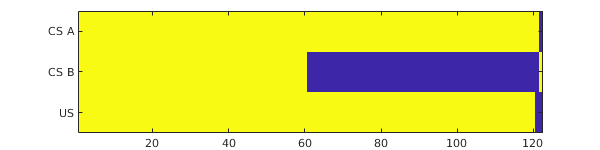

figure('Position', [0   0   600   150])
imagesc([ref_exp_realization.csInput, ref_exp_realization.usInput]')
set(gca, 'YTick', [1 2 3], 'YTickLabel', {'CS A', 'CS B', 'US'})

From the plot we can see we properly specified a backward-blocking design - AB+ is presented in the first stage, followed by A+ in the second stage, finishing with single A- and B- test trials. Since the backward blocking design is deterministic, every other realization of the experiment would be the same.

### Run the evaluation of the reference design

We can now use simulations to evaluate the specified reference design. We will evaluate the design using a large number of single-subject experiments. We use single-subject experiments since they are a more difficult benchmark than group experiments (due to less available data), and because in potential translational applications of model-based analysis (e.g., computational psychiatry) we are ultimately interested in drawing inferences at the level of single subjects.

We can now set up the evaluation and run it; however, here we just list the code, without executing it, since it can take a while to run (if you run it, you can speed up the execution using parallel computing, indicated by the `parallel` flag below):

Instead of running the evaluation, we will load the pre-computed results (which are also analyzed in the paper). The result files are available from OSF ([https://osf.io/xgnm4/](https://osf.io/xgnm4/)) and you will need to unpack them into the root of the project directory. The relevant part of the directory tree should look like this (we focus on the results from Scenario 2, here denoted by `kru2008`):

Let us load the evaluation results for the reference backward blocking, evaluated under a point prior (as we have defined above):

% Load point prior evaluation results of backward blocking
warning('off', 'MATLAB:dispatcher:UnresolvedFunctionHandle')
load(fullfile('../../results/kru2008/kru2008_eval_design-bb_prior-point/kru2008_eval_design-bb_prior-point.mat'), 'sim_info');
eval_ref = sim_info.results_eval;

### Inspect the design evaluation results

We can first inspect the obtained loss value:

eval_ref.loss

ans = -0.3876

However, since loss is expressed as the log-odds of incorrect model selection, it is not so easy to directly interpret it. Helpfully, the loss function returns also the auxiliary information from which the loss was computed:

eval_ref.outputs.loss_info

ans = struct with fields:
        confusion_matrix: [2×2 double]
                 avg_acc: 0.5957
                 avg_err: 0.4043
        is_loss_adjusted: 0
    adjusted_conf_matrix: [2×2 double]
        adjusted_avg_acc: 0.5957
        adjusted_avg_err: 0.4043


Here we can read off the accuracy (or error) of model selection. In the present case the adjusted accuracy (or error) are the same as unadjusted; the values will differ when the unadjusted accuracy is 1.0 or 0.0 - in this case the confusion matrix is modified by adding or subtracting half an observation to/from the diagonal, to make the log-odds finite. 

It is also instructive to inspect the confusion matrix:

cm_ref = eval_ref.outputs.loss_info.confusion_matrix

cm_ref =    250     6
   201    55


The rows of the confusion matrix index the ground truth model, and the columns index the selected model. The order of the models is the same as we have defined in the model space above (RW, KRW in the present case). We can see that when the RW model is true, it is almost always correctly identified; however, when the KRW model is true, it is very often confused for the RW model. The ground-truth-wise accuracies can be obtained as follows:

accuracies_ref = diag(cm_ref)./sum(cm_ref, 2)

accuracies_ref =     0.9766
    0.2148


Here we can see that the accuracy for RW ground truth is very high, whereas for the KRW ground truth the accuracy is below chance level. We will now try to improve upon this using an optimized design.

## Optimize the design for accurate model selection

### Specify the experiment structure and design space

To obtain an optimized design, we first need to define the experiment structure. The experiment structure is a function (deterministic or stochastic) that maps the values of design variables into concrete experiment realizations (in case of classical conditioning these are sequences of cues and outcomes). 

% Specify the structure of the optimized experiment
optim_exp_design_func = @exp_twostage_twocuecmpnd; % Handle to the function used to generate experiment stimuli from design variables
               

We now have to specify the design variables, both fixed and tunable ones (please note, we omit redundant variables, e.g., given P(A) and P(B), we don't need to provide P(AB), as the sum of probabilities has to be 1):

% Specify the constant and tunable design variables of the experiment
optim_desvars_const = struct(... % Fixed design variables (variables which are not optimized, but are required to generate exp. realization)
    'n_sub', 1,... % Number of simulated subjects per experiment
    'nTrialsAll', [61, 61]); % Trials per each stage (for comparability, we match the total number of trials with the reference design)

optim_desvars_tuned = { % Tunable design variables (with their types and possible value ranges); this defines the design space to search
    struct(...
        'name', 'probA_1',... % Probability of cue A (in stage 1)
        'range', [0, 1],...
        'type', 'real'),...
    struct(...
        'name', 'probB_1',...
        'range', [0, 1],...
        'type', 'real'),...
    struct(...
        'name', 'probUS_A_1',... % Probability of US following cue A (in stage 1)
        'range', [0, 1],...
        'type', 'real'),...
    struct(...
        'name', 'probUS_B_1',... 
        'range', [0, 1],...
        'type', 'real'),...
    struct(...
        'name', 'probUS_AB_1',... % Probability of US following cue AB (in stage 1)
        'range', [0, 1],...
        'type', 'real'),...
    struct(...
        'name', 'probA_2',... % Probability of cue A (in stage 2)
        'range', [0, 1],...
        'type', 'real'),...
    struct(...
        'name', 'probB_2',...
        'range', [0, 1],...
        'type', 'real'),...
    struct(...
        'name', 'probUS_A_2',...
        'range', [0, 1],...
        'type', 'real'),...
    struct(...
        'name', 'probUS_B_2',...
        'range', [0, 1],...
        'type', 'real'),...
    struct(...
        'name', 'probUS_AB_2',...
        'range', [0, 1],...
        'type', 'real')
    };

### Specify the design priors

Next, we need to specify the evaluation prior that will be used to evaluate candidate designs in the optimization process - this is termed the *design prior*. In practice, the evaluation prior and the design prior will coincide (you want to use the same knowledgebase both to evaluate and optimize designs); however, here the evaluation prior is a point prior representing a known ground-truth, and therefore the design prior is different - it is a proper distribution over parameters. We specify the design priors for parameters of each model. The design prior over models is not specified, but it is rather assumed to be uniform (this is implemented by simulating the same number of experiments from each model).

% Specify vague design prior for the RW model
rw_vague_design_prior = struct(...
    'evo', struct(...
        'wInit', 0.0,...% Value taken from Kruschke (2008)
        'alpha', @() unifrnd(0,1)),... % Vague prior on learning rate
    'obs', struct(...
        'intercept', 0.0,... % This can be fixed without loss of generality
        'slope', 1.0,... % This can be fixed without loss of generality
        'sd', @() unifrnd(0.05,0.5))); % Vague prior on noise level
 
% Specify vague design prior for the KRW model
krw_vague_design_prior = struct(...
    'evo', struct(...
        'wInit', 0.0,...
        'logSigmaWInit', @() normrnd(0, 2),... % Mean value taken from Kruschke (2008), SD supposed to result in vagueness
        'logTauSq',  -20,... % Approx. 0 when exponentiated; value taken from Kruschke (2008)
        'logSigmaRSq', @() normrnd(0, 2)),... % Original value 1.3863 taken from Kruschke (2008); Here the prior should be vague 
    'obs', struct(...
        'intercept', 0.0,...
        'slope', 1.0,...
        'sd', @() unifrnd(0.05,0.5))); % Vague prior on noise level
    
        
% Aggregate design priors
vague_design_priors = {rw_vague_design_prior, krw_vague_design_prior};

### Run the design optimization

We are now ready to configure the optimization and run it. The most important options below are the number of experiments to use for evaluating a single design (`n_exp`), and the number of iterations (`MaxObjectiveEvaluations`) that will be used in optimization, some of which are the initial randomly chosen seed points (`NumSeedPoints`). Alternatively or additionally, we can impose a restriction on the maximum optimization time (`MaxTime`). It is also important to set constraints on the probabilities, such that probabilities of mutually exclusive events sums to one (see `XConstraintFcn`). Since the optimization below will take hours to run, we just list the code without executing it.

Instead of running the optimization, we again load pre-computed results from OSF (as we did with design evaluation above).

% Load results of design optimization
warning('off', 'MATLAB:dispatcher:UnresolvedFunctionHandle')
load(fullfile('../../results/kru2008/kru2008_optim_prior-vague/kru2008_optim_prior-vague.mat'), 'sim_info');
results_optim = sim_info.results_optim

results_optim = struct with fields:
                      ObjectiveFcn: @(d)obj_func(d,cfg_optim_parsed)
              VariableDescriptions: [10×1 optimizableVariable]
                           Options: [1×1 struct]
                      MinObjective: -4.8442
                   XAtMinObjective: [1×10 table]
             MinEstimatedObjective: -2.6997
          XAtMinEstimatedObjective: [1×10 table]
           NumObjectiveEvaluations: 300
                  TotalElapsedTime: 1.9355e+04
                         NextPoint: [1×10 table]
                            XTrace: [300×10 table]
                    ObjectiveTrace: [300×1 double]
                  ConstraintsTrace: []
      ObjectiveEvaluationTimeTrace: [300×1 double]
                IterationTimeTrace: [300×1 double]
                        ErrorTrace: [300×1 double]
                  FeasibilityTrace: [300×1 logical]
       FeasibilityProbabilityTrace: [300×1 double]
               IndexOfMinimumTrace: [300×1 double]
             

### Inspect the design optimization results

We can now check the values of optimized design variables. Bayesian optimization returns two optimized designs, one that is associated with the lowest observed loss value (`XAtMinObjective`) and one that is associated with the minimum estimated loss, based on the optimizers internal model of the loss function (`XAtMinEstimatedObjective`). Going forward, we use this latter design.

results_optim.XAtMinEstimatedObjective

ans = 1×10 table
     probA_1     probB_1    probUS_A_1    probUS_B_1    probUS_AB_1    probA_2    probB_2     probUS_A_2    probUS_B_2    probUS_AB_2
    _________    _______    __________    __________    ___________    _______    ________    __________    __________    ___________

    0.0087378    0.63019     0.57455       0.99449       0.053091      0.76009    0.019426     0.86485       0.57181        0.69376  


We can also inspect how the lowest estimated loss value evolved over iterations, to see if it was still improving when we stopped the optimization, or if it leveled out (indicating possible convergence).

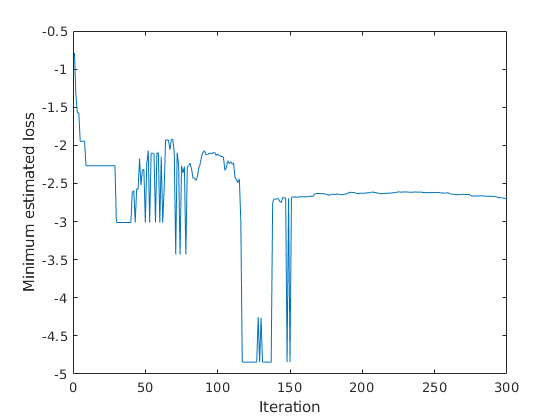

figure
plot(results_optim.EstimatedObjectiveMinimumTrace)
xlabel('Iteration')
ylabel('Minimum estimated loss')

We can see that for the last 150 iterations the estimated minimum loss was pretty stable, indicating possible convergence. We can also inspect the running time.

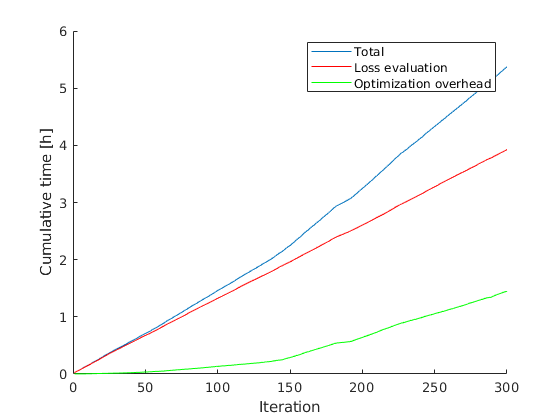

figure
hold on
plot(cumsum(results_optim.IterationTimeTrace)/3600) % We take the cumulative time to 'iron out' iteration-wise variation
plot(cumsum(results_optim.ObjectiveEvaluationTimeTrace)/3600, 'r')
plot(cumsum(results_optim.IterationTimeTrace - results_optim.ObjectiveEvaluationTimeTrace)/3600, 'g')
xlabel('Iteration')
ylabel('Cumulative time [h]')
legend({'Total', 'Loss evaluation', 'Optimization overhead'})

From this plot we can see that the cumulative evaluation time grows linearly with time, but the overhead of Bayesian optimization grows polynomially. We need to be mindful of this for long optimization runs (here the optimization run is short enough to be dominated by the loss evaluation, rather than the optimization overhead).

## Evaluate the optimized design

We will now proceed to evaluate the optimized design in a separate set of simulations, in the same manner as we evaluated the reference design.

### Specify the optimized experiment design

First, we specify the optimized design (i.e., we copy over the values of design variables obtained through optimization and add any fixed variables).

% Specify the chosen optimized design
optimized_desvars = table2struct(results_optim.XAtMinEstimatedObjective); % Optimized values of design variables
optimized_desvars.nTrialsAll = [61, 61]; % Trials per each stage (fixed design variable)

To better understan the design, we can sample a few of its realizations:

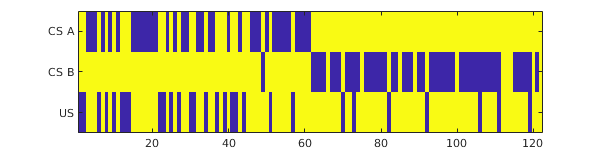

% Obtain few realizations of the optimized design
optim_exp_realization_1 = optim_exp_design_func(optimized_desvars);
optim_exp_realization_2 = optim_exp_design_func(optimized_desvars);

figure('Position', [0   0   600   150])
imagesc([optim_exp_realization_1.csInput, optim_exp_realization_1.usInput]')
set(gca, 'YTick', [1 2 3], 'YTickLabel', {'CS A', 'CS B', 'US'})

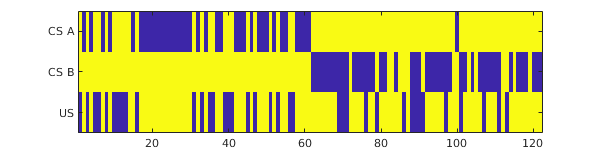

figure('Position', [0   0   600   150])
imagesc([optim_exp_realization_2.csInput, optim_exp_realization_2.usInput]')
set(gca, 'YTick', [1 2 3], 'YTickLabel', {'CS A', 'CS B', 'US'})

### Run the evaluation of the optimized design

We can now evaluate the optimized design (reusing the settings from the evaluation of the reference design). However, this would again take a bit of time, so instead we only list the code and load the pre-computed results.

Again, we load the data obtained from OSF:

% Load point prior evaluation results of the design optimized under a vague
% design prior
warning('off', 'MATLAB:dispatcher:UnresolvedFunctionHandle')
load(fullfile('../../results/kru2008/kru2008_eval_design-vagueopt_prior-point/kru2008_eval_design-vagueopt_prior-point.mat'), 'sim_info');
eval_optim = sim_info.results_eval;

### Inspect the evaluation results

We can first inspect the obtained loss value:

eval_optim.loss

ans = -6.2364

We see that the obtained loss is much lower than for the reference design. 

Next, we can inspect the more easily interpretable confusion matrix and ground-truth-wise accuracies:

eval_optim.outputs

ans = struct with fields:
    simulation_params: {2×1 cell}
                 data: [1×256×2 struct]
              latents: [1×256×2 struct]
      fitting_results: {2×1 cell}
            loss_info: [1×1 struct]


cm_optim = eval_optim.outputs.loss_info.confusion_matrix

cm_optim =    255     1
     0   256


accuracies_optim = diag(cm_optim)./sum(cm_optim, 2)

accuracies_optim =     0.9961
    1.0000


From these results we can see that the optimized design has resulted in almost perferct model identification accuracy.

## Compare the evaluation results of the reference and optimized designs

We can easily compare the two designs by plotting the confusion matrices obtained in their evaluation:

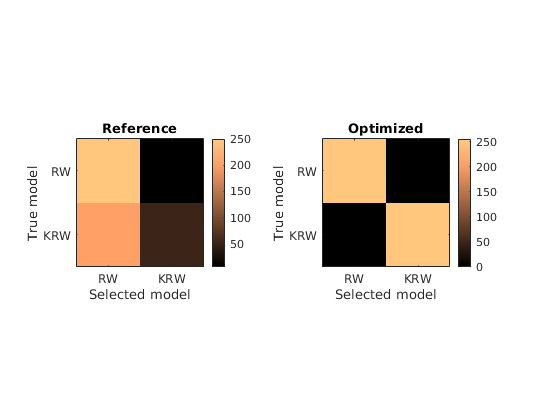

figure
colormap('copper')
subplot(1,2,1)
imagesc(cm_ref)
xlabel('Selected model')
ylabel('True model')
set(gca, 'YTick', [1, 2], 'YTickLabel', {'RW', 'KRW'}, 'XTick', [1, 2], 'XTickLabel', {'RW', 'KRW'})
axis('image')
colorbar()
title('Reference')

subplot(1,2,2)
imagesc(cm_optim)
xlabel('Selected model')
ylabel('True model')
set(gca, 'YTick', [1, 2], 'YTickLabel', {'RW', 'KRW'}, 'XTick', [1, 2], 'XTickLabel', {'RW', 'KRW'})
axis('image')
colorbar()
title('Optimized')

From this figure we can see that the optimized design results in a much 'healthier' confusion matrix. In particular, we see a large increase in model selection accuracy when the presumed ground truth model is the more complex KRW model.

## References

- Rescorla, R. A., & Wagner, A. R. (1972). A theory of Pavlovian conditioning: Variations in the effectiveness of reinforcement and nonreinforcement. *Classical conditioning II: Current research and theory*, *2*, 64-99.

- Dayan, P., & Kakade, S. (2001). Explaining away in weight space. In *Advances in neural information processing systems *(pp. 451-457).

- Kruschke, J. K. (2008). Bayesian approaches to associative learning: From passive to active learning. *Learning & behavior*, *36*(3), 210-226.